# SISO system

## Define plant

opt = stepDataOptions('StepAmplitude',2);

### Parameters (spring mass damper)

k = 1;
m = 1;
b = 0.2;

k_u =ureal('k_u',1,'Percentage',20)


k_u =

  Uncertain real parameter "k_u" with nominal value 1 and variability [-20,20]%.



b_u =ureal('b_u',0.5,'Percentage',20)


b_u =

  Uncertain real parameter "b_u" with nominal value 0.5 and variability [-20,20]%.



m_u =ureal('m_u',1,'Percentage',20)


m_u =

  Uncertain real parameter "m_u" with nominal value 1 and variability [-20,20]%.




c_u = ureal('c_u',1,'Percentage',30)


c_u =

  Uncertain real parameter "c_u" with nominal value 1 and variability [-30,30]%.



state_feedback_noise = ureal('state_feedback_noise',1,'Percentage',30)


state_feedback_noise =

  Uncertain real parameter "state_feedback_noise" with nominal value 1 and variability [-30,30]%.



### State Space Model

#### Nominal Values

A = [0,1;-k/m,-b/m];
B = [0;1/m];
C = [1,0];
D = [0];
Ca = [C;eye(size(A))];
Da = [D;zeros(length(A),1)];
plant = ss(A,B,C,D);
plant.InputName = {'u force'};
plant.StateName={'x','xdot'};
plant.OutputName={'position'};

plant_aug = ss(A,B,Ca,Da);
plant_aug.InputName = {'u force'};
plant_aug.StateName={'x','xdot'};
plant_aug.OutputName={'position','x','xdot'};


#### With uncertainty

A = [0,1;-k_u/m_u,-b_u/m_u];
B = [0;1/m_u];
C = [c_u,0];
D = [0];
Ca = [C;diag([state_feedback_noise,state_feedback_noise])];
Da = [D;0;0];
plant_u = ss(A,B,C,D);
plant_u.InputName = {'u force'};
plant_u.StateName={'x','xdot'};
plant_u.OutputName={'position'};

plant_aug_u = ss(A,B,Ca,Da);
plant_aug_u.InputName = {'u force'};
plant_aug_u.StateName={'x','xdot'};
plant_aug_u.OutputName={'position','x','xdot'};

controller_none = ss(0)


controller_none =
 
  D = 
       u1
   y1   0
 
Static gain.



controller_none.InputName = {'position'};
controller_none.OutputName={'u force'};

### Responce

report.base = test_plant(plant)

report = struct with fields:
    base: [1×1 struct]


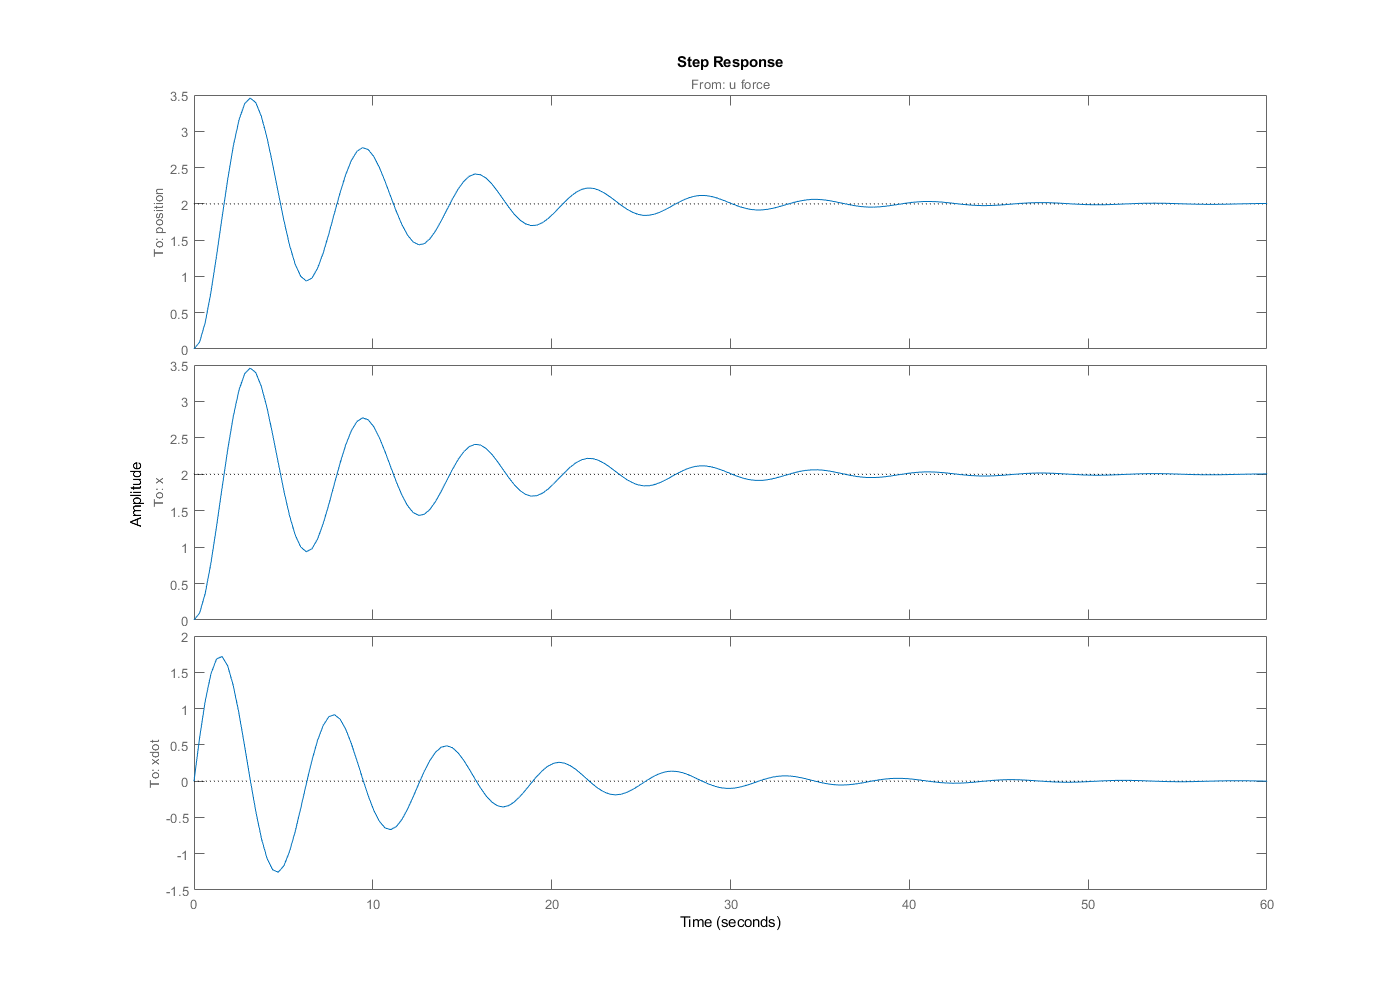


step(plant_aug,opt)

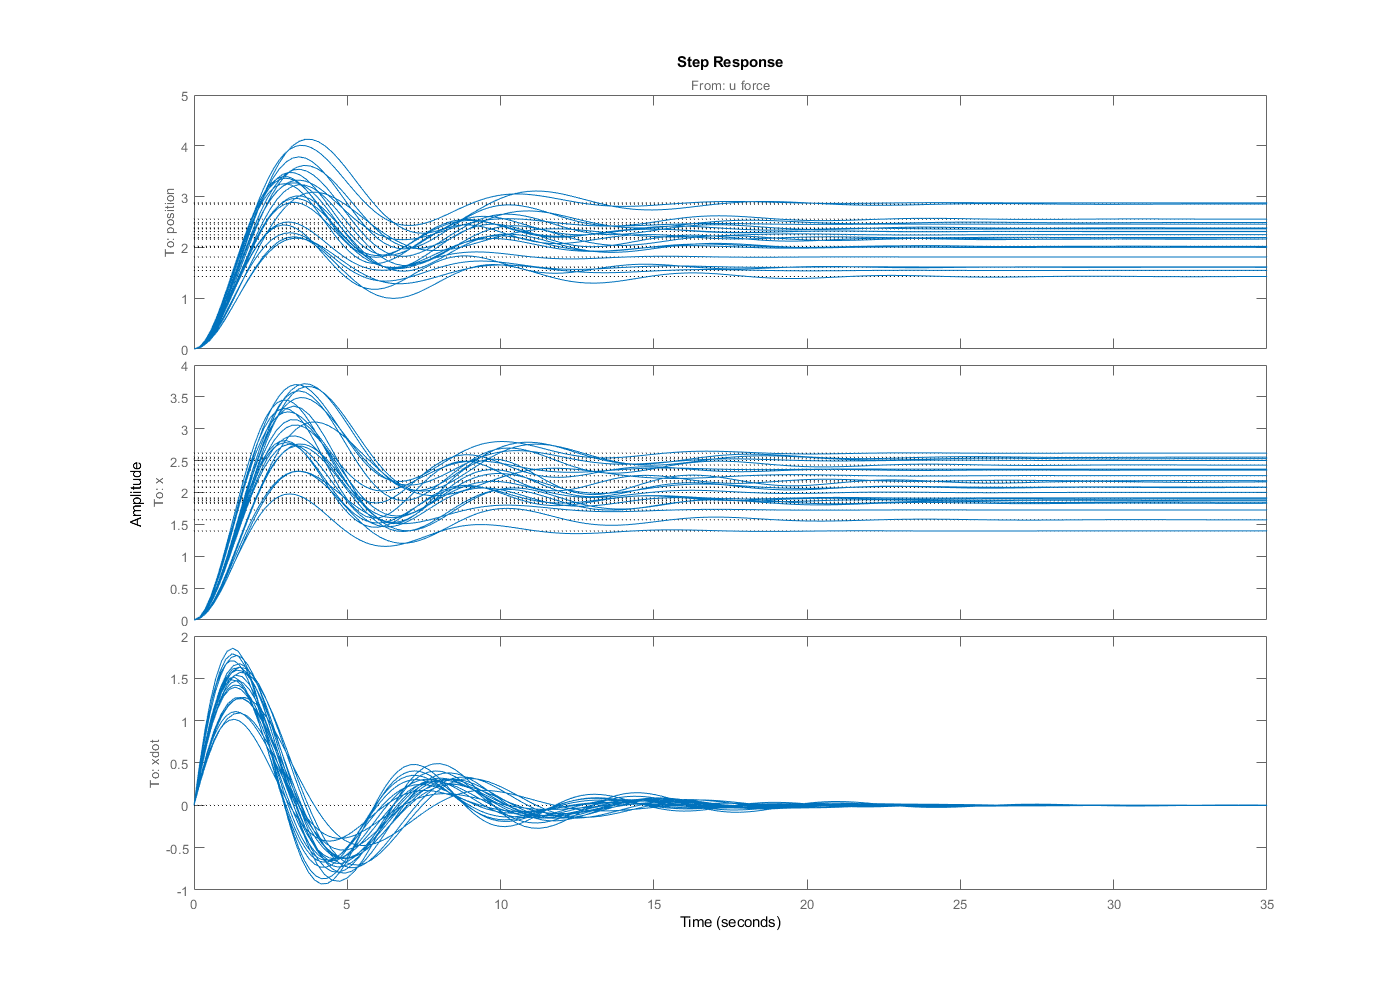

%pzplot(plant)
%nyquist(plant)

step(plant_aug_u,opt)

## Controller

### LQR

#### Parameters (gains)

Q = diag([1,1]);
R = 1;

#### Controler

[K_LQR,S_LQR,e_LQR] = lqr(plant,Q,R,[0,0]');
controller_LQR = ss(K_LQR);
controller_LQR.InputName = {'x','xdot'};
controller_LQR.OutputName={'u force'};
LQR_plant = feedback(plant_aug_u,controller_LQR,'name',-1);
LQR_plant_true = feedback(plant_aug,controller_LQR,'name',-1);

### Responce

report.lqr = test_plant(LQR_plant)

report = struct with fields:
    base: [1×1 struct]
     lqr: [1×1 struct]


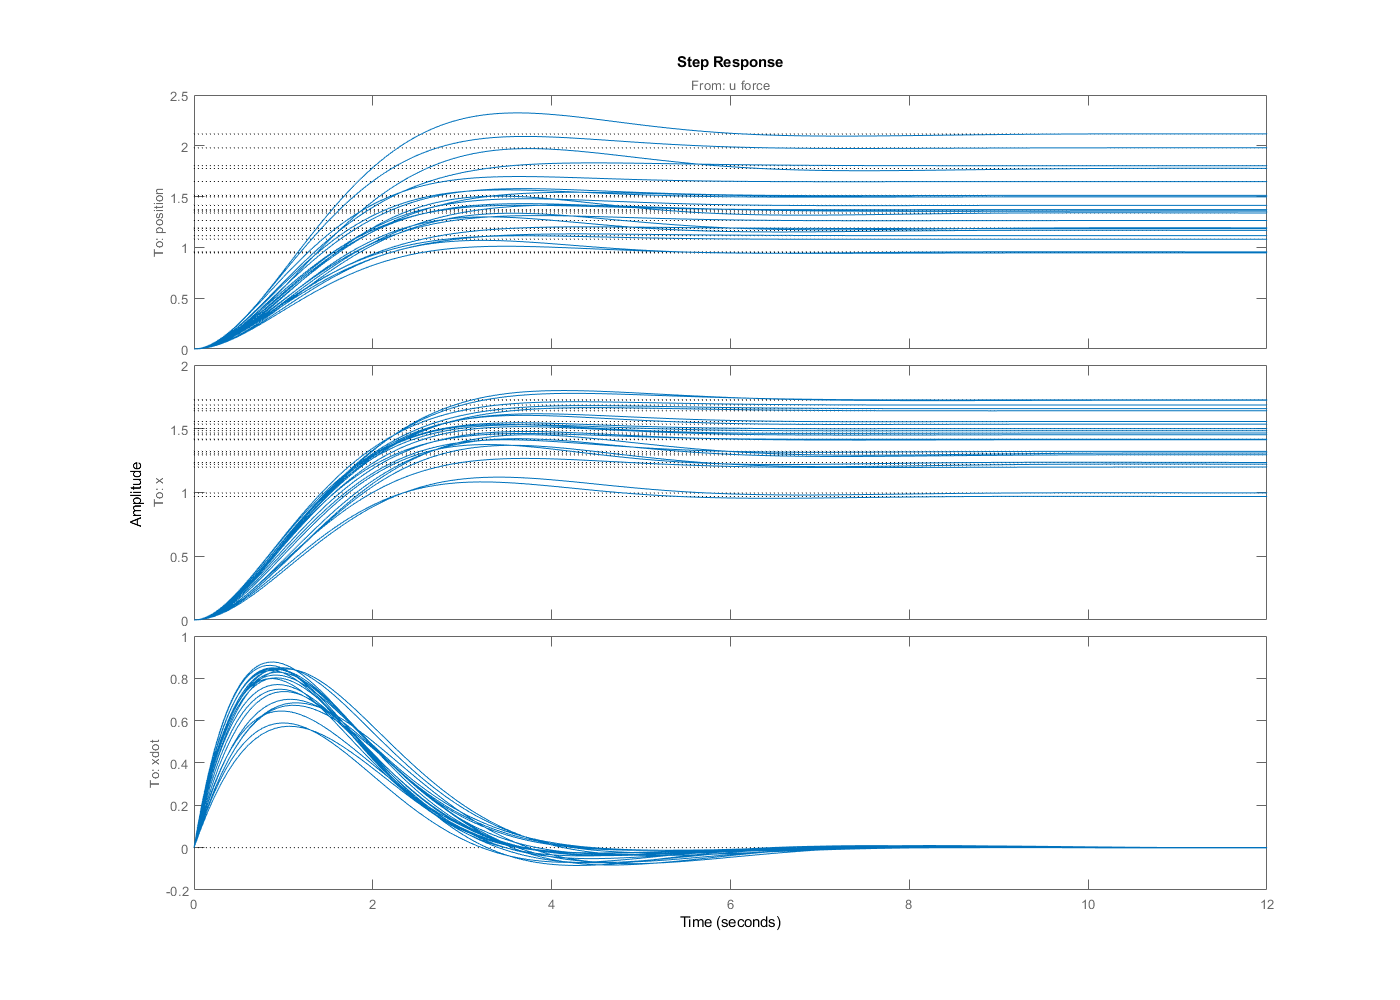

step(LQR_plant,opt)

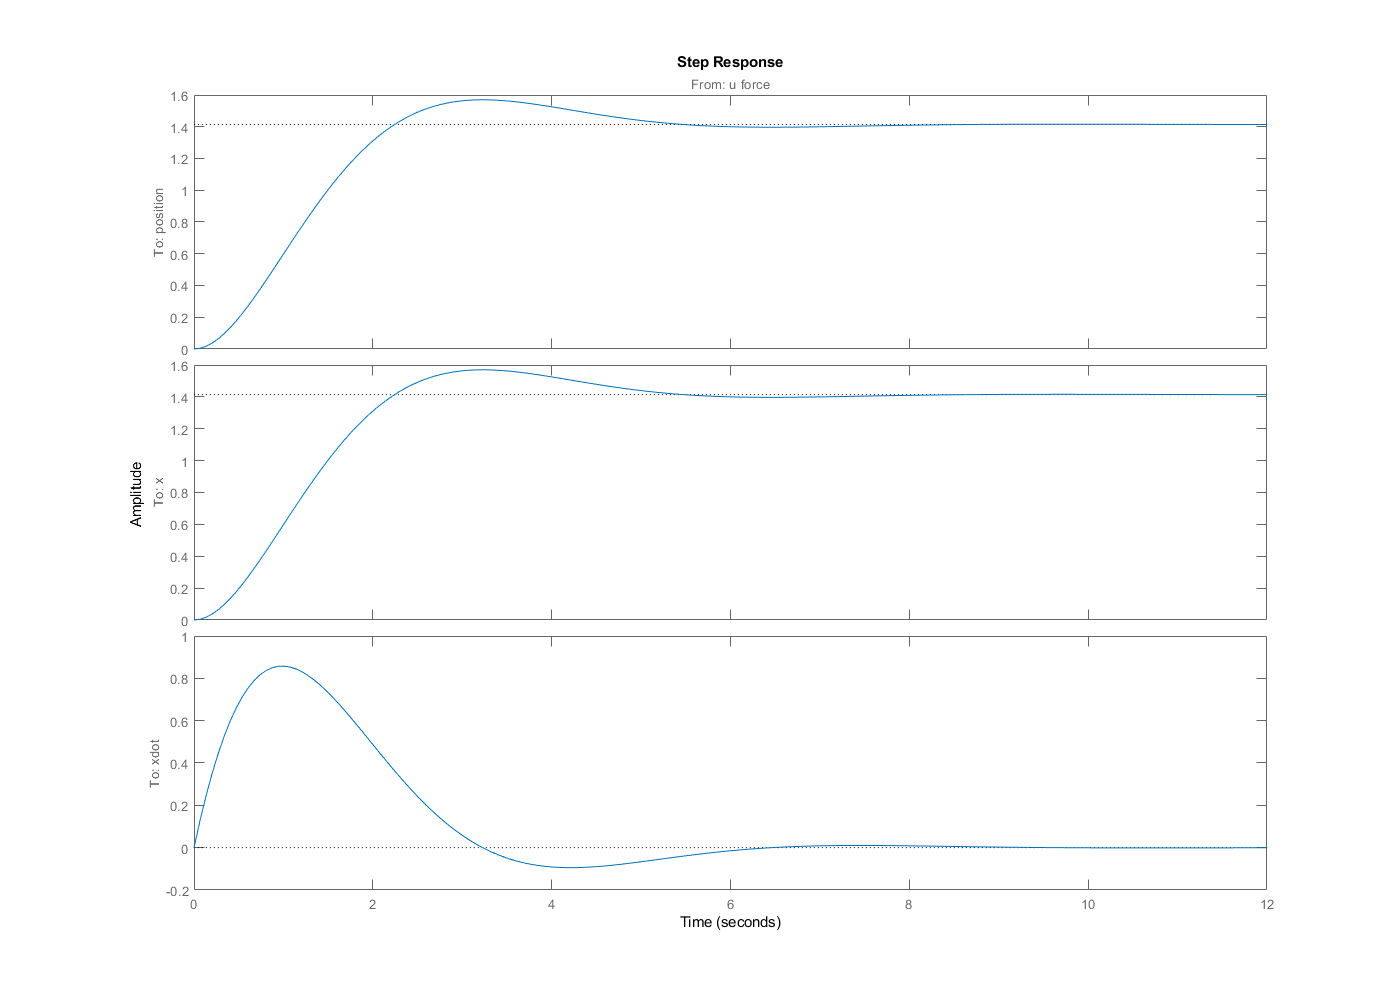

step(LQR_plant_true,opt)

%pzplot(LQR_plant)
%nyquist(LQR_plant)

### LQG

#### Parameters (gains)

nx = 2;    %Number of states
ny = 1;    %Number of outputs
Qn = [4 2; 2 1];
Rn = 0.7;
R = [1]

R = 1

QXU = blkdiag(0.1*eye(nx),R);
QWV = blkdiag(Qn,Rn);


#### Controler

[K_LQG] = lqg(plant,QXU,QWV);
controller_LQG = ss(K_LQG);
controller_LQG.InputName = {'position'};
controller_LQG.OutputName={'u force'};
LQG_plant = feedback(plant_aug_u,controller_LQG,'name',1);
LQG_plant_true = feedback(plant_aug,controller_LQG,'name',1);

### Responce

report.lqr = test_plant(LQG_plant)

report = struct with fields:
    base: [1×1 struct]
     lqr: [1×1 struct]


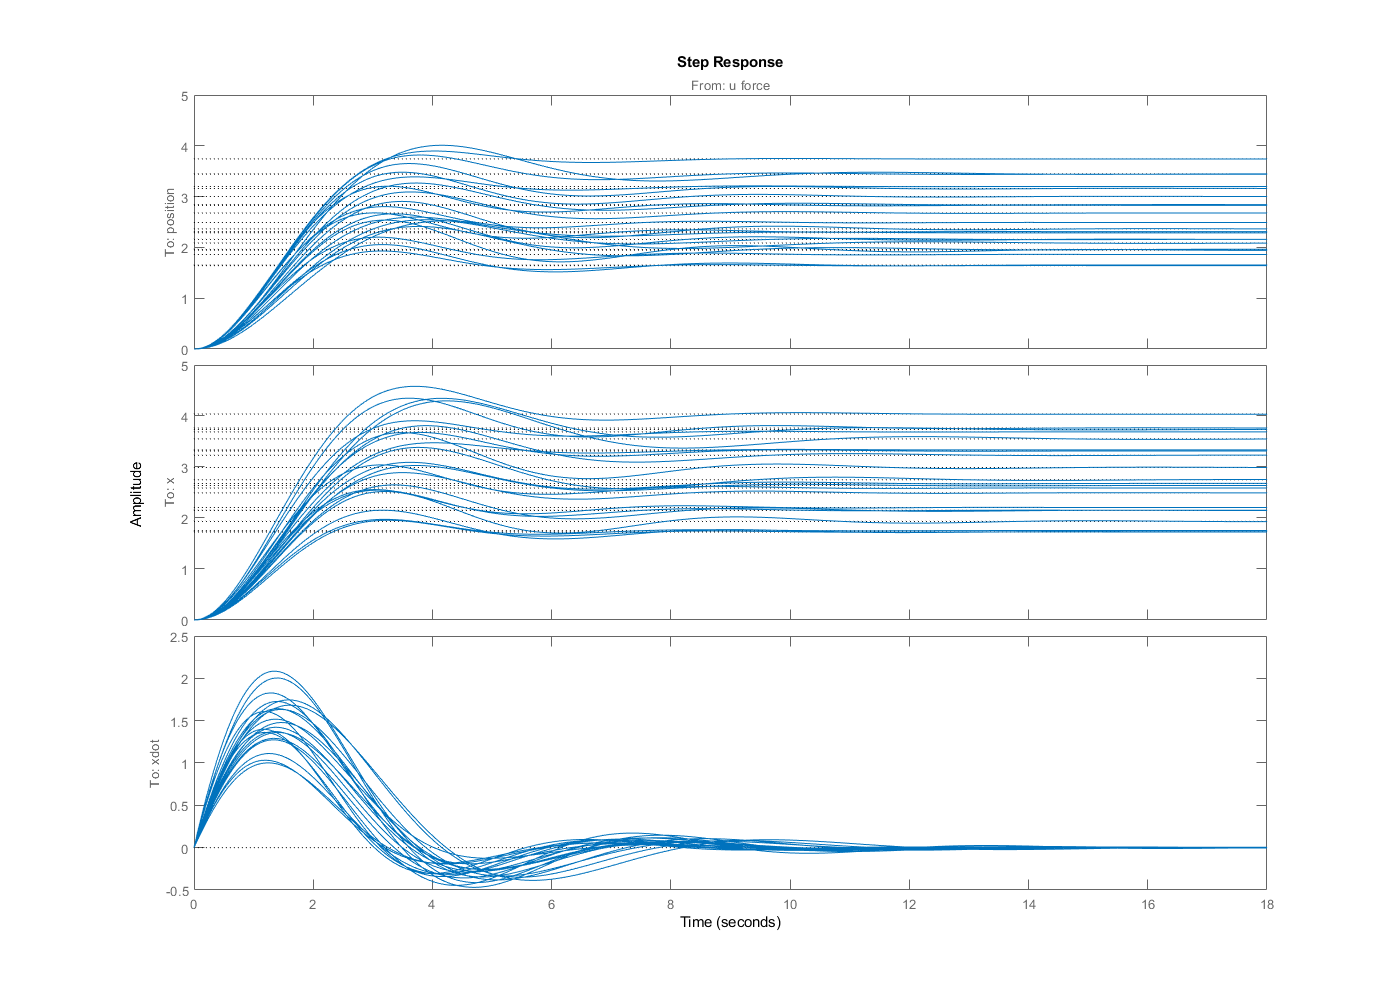

step(LQG_plant,opt)

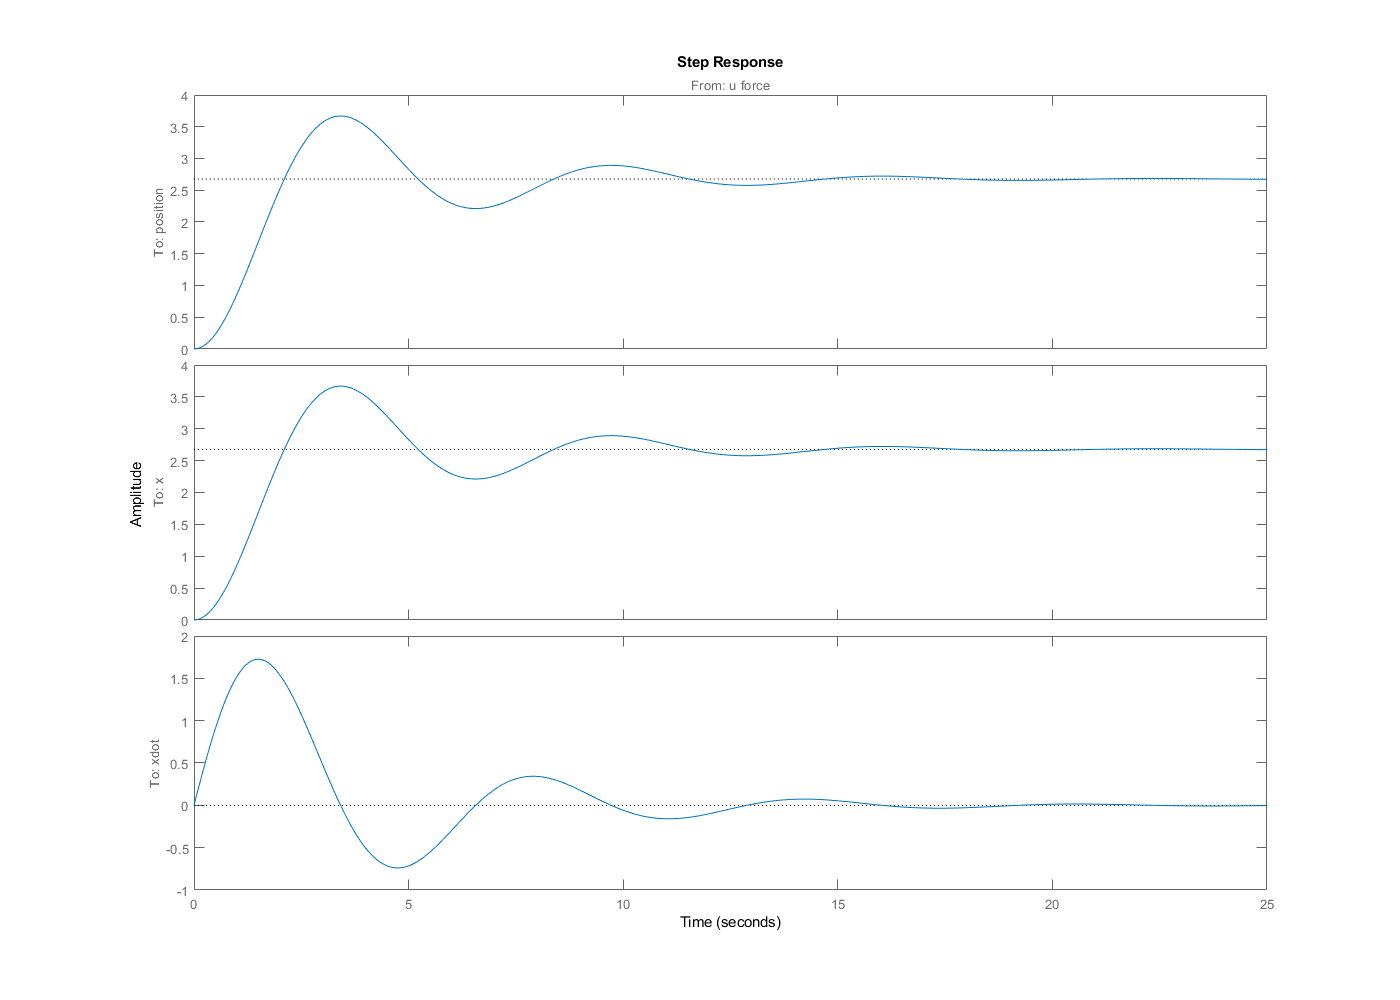

step(LQG_plant_true,opt)

%pzplot(LQR_plant)
%nyquist(LQR_plant)

### Hinf

#### Parameters (gains)

cutoff_hz = 0.45

cutoff_hz = 0.4500

wc = 2*pi*cutoff_hz;
We = tf([0,wc],[1,wc]); % lowpass filter

cutoff_hz = 1000

cutoff_hz = 1000

wc = 2*pi*cutoff_hz;
Wu = tf([1,0],[1,wc]); %high pass filter

Winput = tf([0,1],[0,1]);

Wsensor = tf([0,1],[0,1]);


#### Genarlized Plant

P = tf(plant_u)


P =
 
  From input "u force" to output "position":
         1
  ---------------
  s^2 + 0.5 s + 1
 
Continuous-time transfer function.



% w = [sensor,input]
% z = [error,command]
G11hat = [We*Wsensor We*P*Winput;0 0]; % w->z % sensor all comes from u
G12hat = [We*P;Wu]; % u->z
G21hat = [eye(1) P];% w->y
G22hat = P; % u->y
Ghat = [G11hat G12hat;G21hat G22hat];
G = ss(Ghat,'minimal');

#### Controler

[K_INF,~,Gam,info_inf] = hinfsyn(G,1,1,[.1,1.2],'DISPLAY','on');


  Test bounds:  0.182 <=  gamma  <=  1.2

   gamma        X>=0        Y>=0       rho(XY)<1    p/f
  1.20e+00     1.2e-05     0.0e+00     8.935e-03     p
  4.67e-01     1.3e-05     1.7e-18     1.071e-01     p
  2.91e-01    -1.5e+00 #  -1.0e-17     2.993e-04     f
  3.69e-01     1.3e-05     0.0e+00     4.326e-01     p
  3.28e-01    -2.3e+01 #   2.2e-17     2.179e-04     f
  3.48e-01     1.3e-05    -5.0e-17     1.015e+00 #   f
  3.58e-01     1.3e-05     1.3e-18     6.131e-01     p
  3.53e-01     1.3e-05     0.0e+00     7.668e-01     p
  3.50e-01     1.3e-05     0.0e+00     8.743e-01     p

  Best performance (actual): 0.35



controller_Hinf = ss(K_INF);
controller_Hinf.InputName = {'position'};
controller_Hinf.OutputName={'u force'};
Hinf_plant = feedback(plant_u,controller_Hinf,'name',1);

### Responce

report.hinf = test_plant(Hinf_plant)

report = struct with fields:
    base: [1×1 struct]
     lqr: [1×1 struct]
    hinf: [1×1 struct]


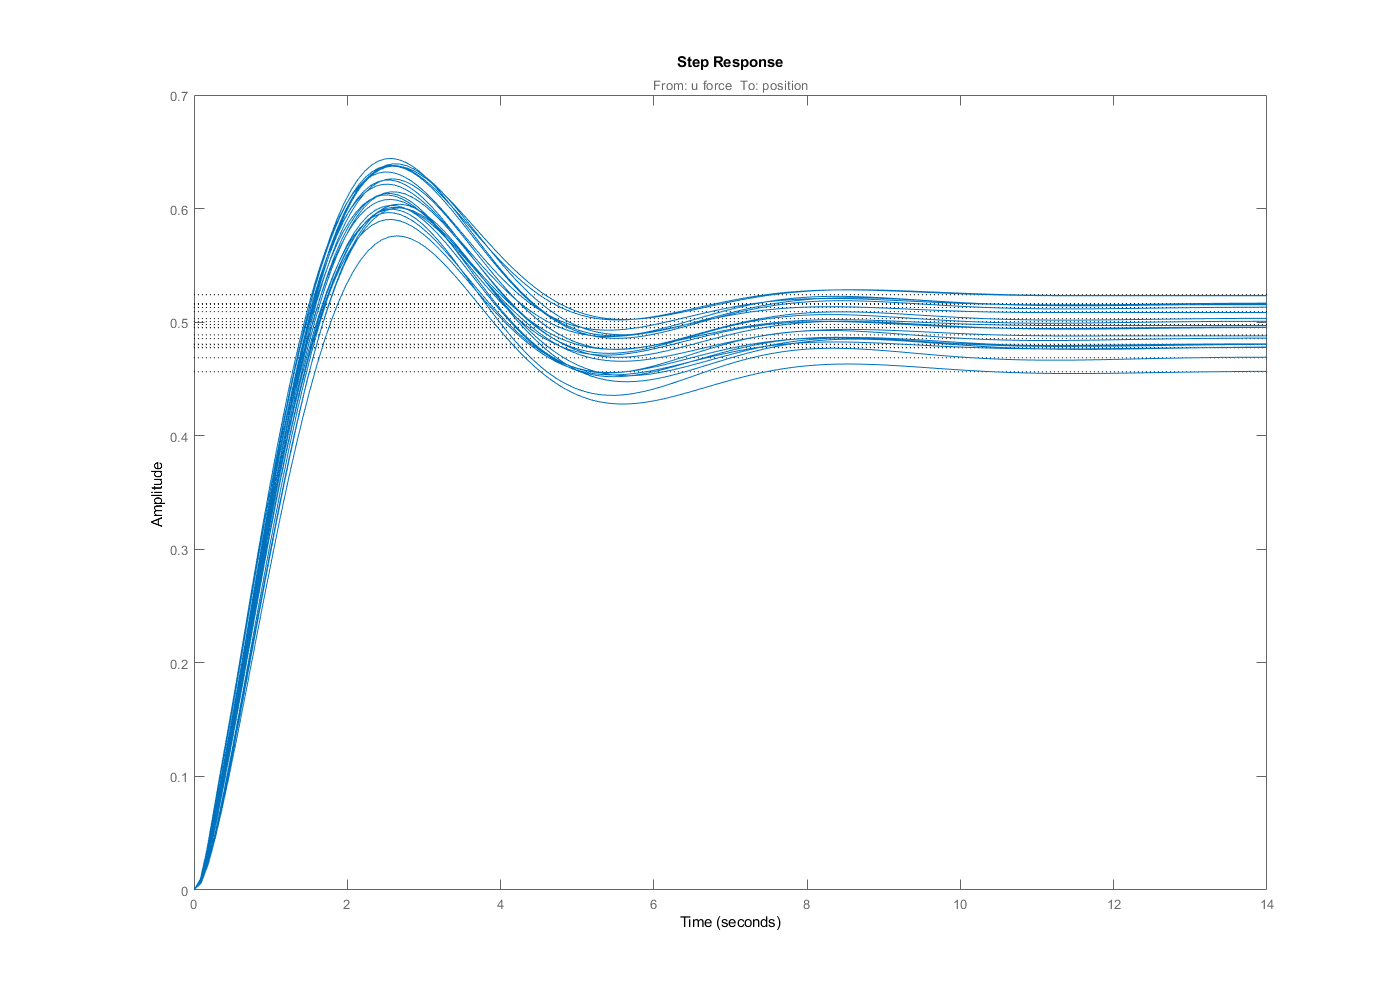

step(Hinf_plant,opt)

%pzplot(Hinf_plant)
%nyquist(Hinf_plant)

### H2

#### Parameters (gains)

cutoff_hz = 0.45

cutoff_hz = 0.4500

wc = 2*pi*cutoff_hz;
We = tf([0,wc],[1,wc]); % lowpass filter

cutoff_hz = 1000

cutoff_hz = 1000

wc = 2*pi*cutoff_hz;
Wu = tf([1,0],[1,wc]);

Winput = tf([0,1],[0,1]);

Wsensor = tf([0,1],[0,1]);


#### Genarlized Plant

P = tf(plant)


P =
 
  From input "u force" to output "position":
         1
  ---------------
  s^2 + 0.2 s + 1
 
Continuous-time transfer function.



% w = [sensor,input]
% z = [error,command]
G11hat = [We*Wsensor We*P*Winput;0 0]; % w->z % sensor all comes from u
G12hat = [We*P;Wu]; % u->z
G21hat = [eye(1) P];% w->y
G22hat = P; % u->y
Ghat = [G11hat G12hat;G21hat G22hat];
G = ss(Ghat,'minimal');

#### Controler

[K_2,~,Gam,info_2] = h2syn(G,1,1);

controller_H2 = ss(K_2);
controller_H2.InputName = {'position'};
controller_H2.OutputName={'u force'};
H2_plant = feedback(plant_u,controller_H2,'name',+1);

### Responce

report.h2 = test_plant(H2_plant)

report = struct with fields:
    base: [1×1 struct]
     lqr: [1×1 struct]
    hinf: [1×1 struct]
      h2: [1×1 struct]


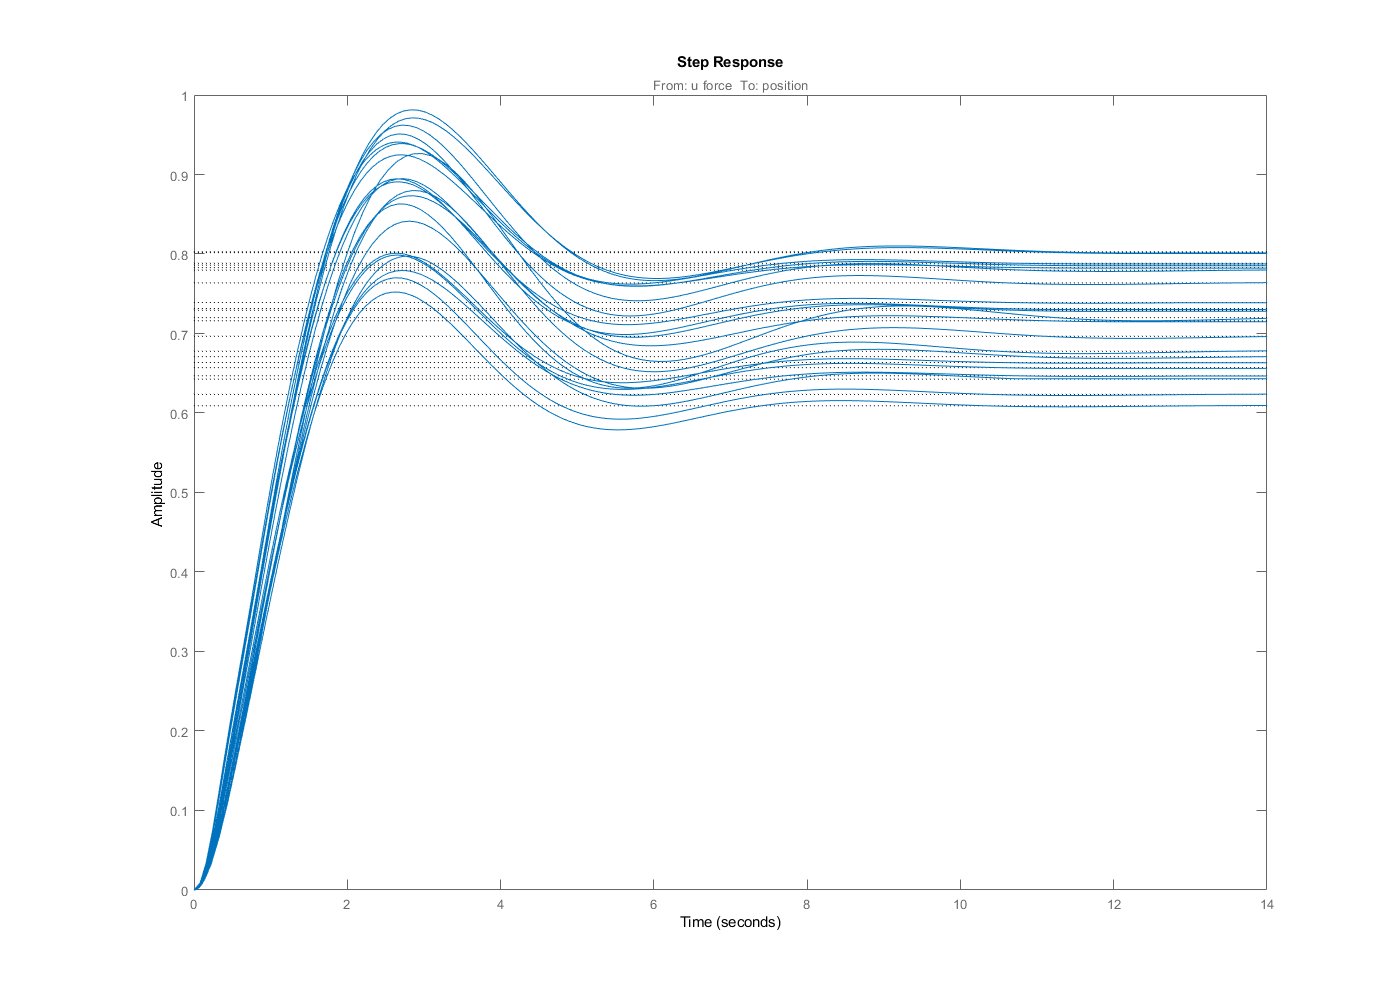

step(H2_plant,opt)

%pzplot(H2_plant)
%nyquist(H2_plant)

### Cascade Control

#### LQR Closed Loop Plant

plant_CL_LQR_u= ss(LQR_plant.A,LQR_plant.B,LQR_plant.C(1,:),LQR_plant.D(1));
plant_CL_LQR_u.InputName = {'u force'};
plant_CL_LQR_u.StateName={'x','xdot'};
plant_CL_LQR_u.OutputName={'position'};

plant_CL_LQR= ss(LQR_plant_true.A,LQR_plant_true.B,LQR_plant_true.C(1,:),LQR_plant_true.D(1));
plant_CL_LQR.InputName = {'u force'};
plant_CL_LQR.StateName={'x','xdot'};
plant_CL_LQR.OutputName={'position'};

#### Parameters (gains) calcualted above in the Hinf section

% cutoff_hz = 120
% wc = 2*pi*cutoff_hz;
% We = tf([0,wc],[1,wc]);
% 
% cutoff_hz = 610
% wc = 2*pi*cutoff_hz;
% Wu = tf([0,1],[1,wc]);
% 
% Winput = tf([0,1],[0,1]);
% 
% Wsensor = tf([0,1],[0,1]);

#### Controler setting

P = tf(plant_CL_LQR_u)


P =
 
  From input "u force" to output "position":
            1
  ---------------------
  s^2 + 1.667 s + 1.414
 
Continuous-time transfer function.



% w = [sensor,input]
% z = [error,command]
G11hat = [We*Wsensor We*P*Winput;0 0]; % w->z % sensor all comes from u
G12hat = [We*P;Wu]; % u->z
G21hat = [eye(1) P];% w->y
G22hat = P; % u->y
Ghat = [G11hat G12hat;G21hat G22hat];
G = ss(Ghat,'minimal');

#### Controler

[K_INF,~,Gam,info_inf] = hinfsyn(G,1,1,[0,1.2],'DISPLAY','on');


  Test bounds:  0.182 <=  gamma  <=  1.2

   gamma        X>=0        Y>=0       rho(XY)<1    p/f
  1.20e+00     1.1e-05     0.0e+00     2.914e-03     p
  4.67e-01     1.2e-05     0.0e+00     3.492e-02     p
  2.91e-01    -1.2e+00 #   2.6e-17     1.088e-04     f
  3.69e-01     1.2e-05     0.0e+00     1.410e-01     p
  3.28e-01    -2.0e+01 #  -4.0e-16     7.903e-05     f
  3.48e-01     1.2e-05     0.0e+00     3.298e-01     p
  3.38e-01     1.2e-05     0.0e+00     8.653e-01     p
  3.33e-01     1.2e-05    -2.1e-16     3.953e+00 #   f
  3.35e-01     1.2e-05     2.4e-17     1.426e+00 #   f

  Best performance (actual): 0.338



controller_cascade = ss(K_INF);
controller_cascade.InputName = {'position'};
controller_cascade.OutputName={'u force'};
cascade_plant = feedback(plant_CL_LQR_u,controller_cascade,'name',+1);

### Responce

report.cascade = test_plant(cascade_plant)

report = struct with fields:
       base: [1×1 struct]
        lqr: [1×1 struct]
       hinf: [1×1 struct]
         h2: [1×1 struct]
    cascade: [1×1 struct]


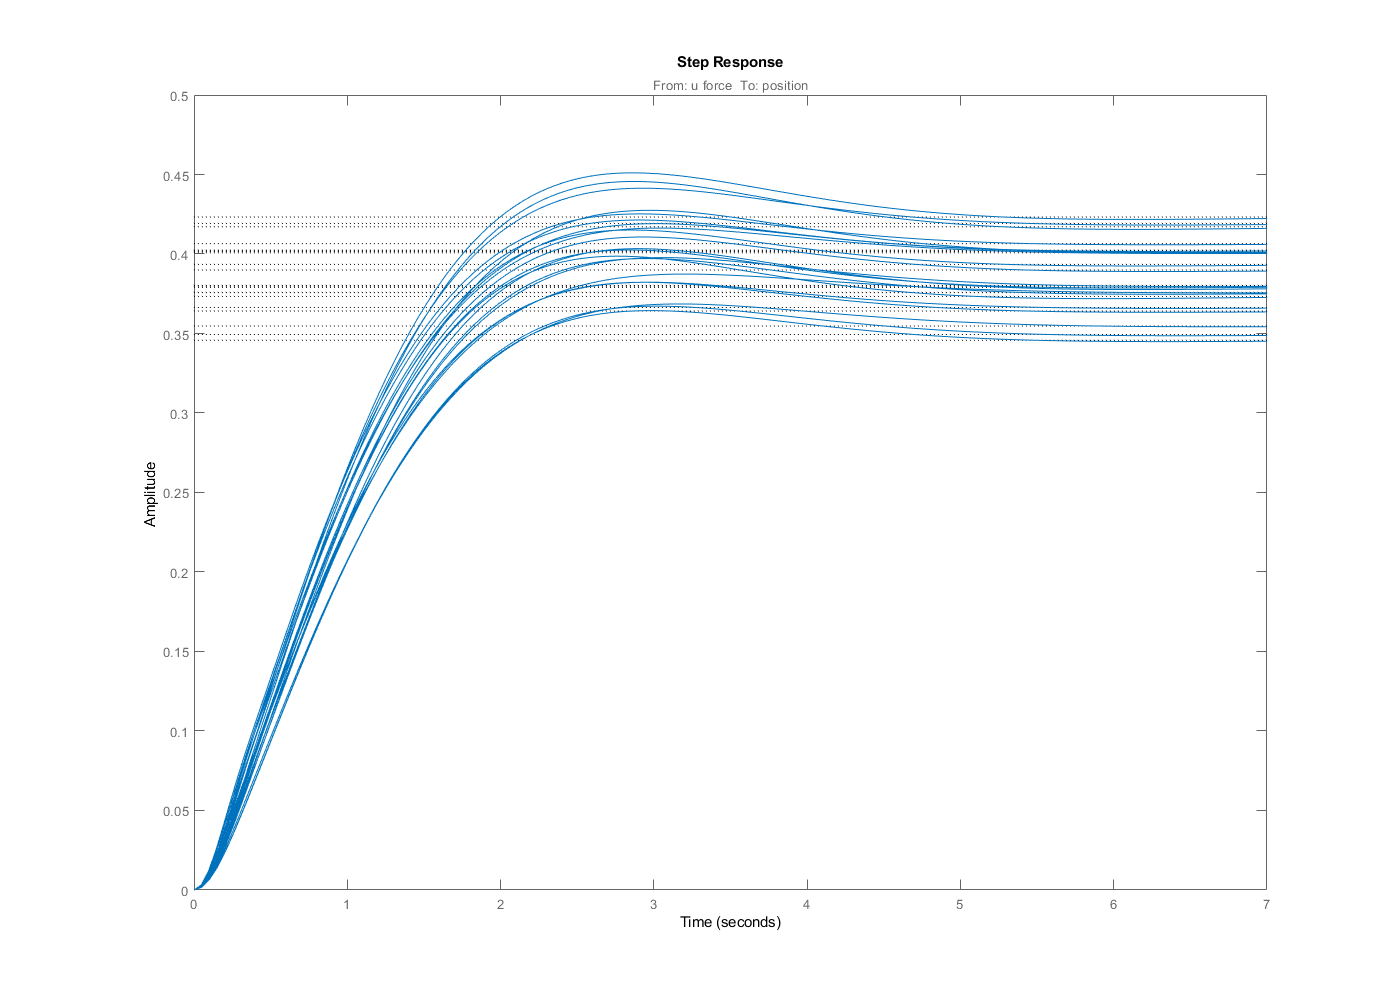

figure;step(cascade_plant,opt)

## Simulink

### Setup varient control

Setup_VariantControl;
NoiseType = Controller_Type.Dont_Use_Noise;
ControlType = Controller_Type.None;

Valid_Controllers = {'Cascade_Hinf_LQR','Hinf','LQR','None','H2','H2_LQR','LQG','Hinf_LQG'};
Valid_Noise = {'Use_Noise','Dont_Use_Noise'};

results.Use_Noise = containers.Map()

results = struct with fields:
         Use_Noise: [0×1 containers.Map]
    Dont_Use_Noise: [8×1 containers.Map]


results.Dont_Use_Noise = containers.Map()

results = struct with fields:
         Use_Noise: [0×1 containers.Map]
    Dont_Use_Noise: [0×1 containers.Map]



model_name = 'Controllers_Disturbances.slx';
power = -10;

for itr_Noise = Valid_Noise
    for itr_Controller = Valid_Controllers
        NoiseType = Controller_Type.(itr_Noise{1});
        ControlType = Controller_Type.(itr_Controller{1});
        results.(itr_Noise{1})(itr_Controller{1}) = sim(model_name,'ReturnWorkspaceOutputs', 'on');
    end
end

### Plot things

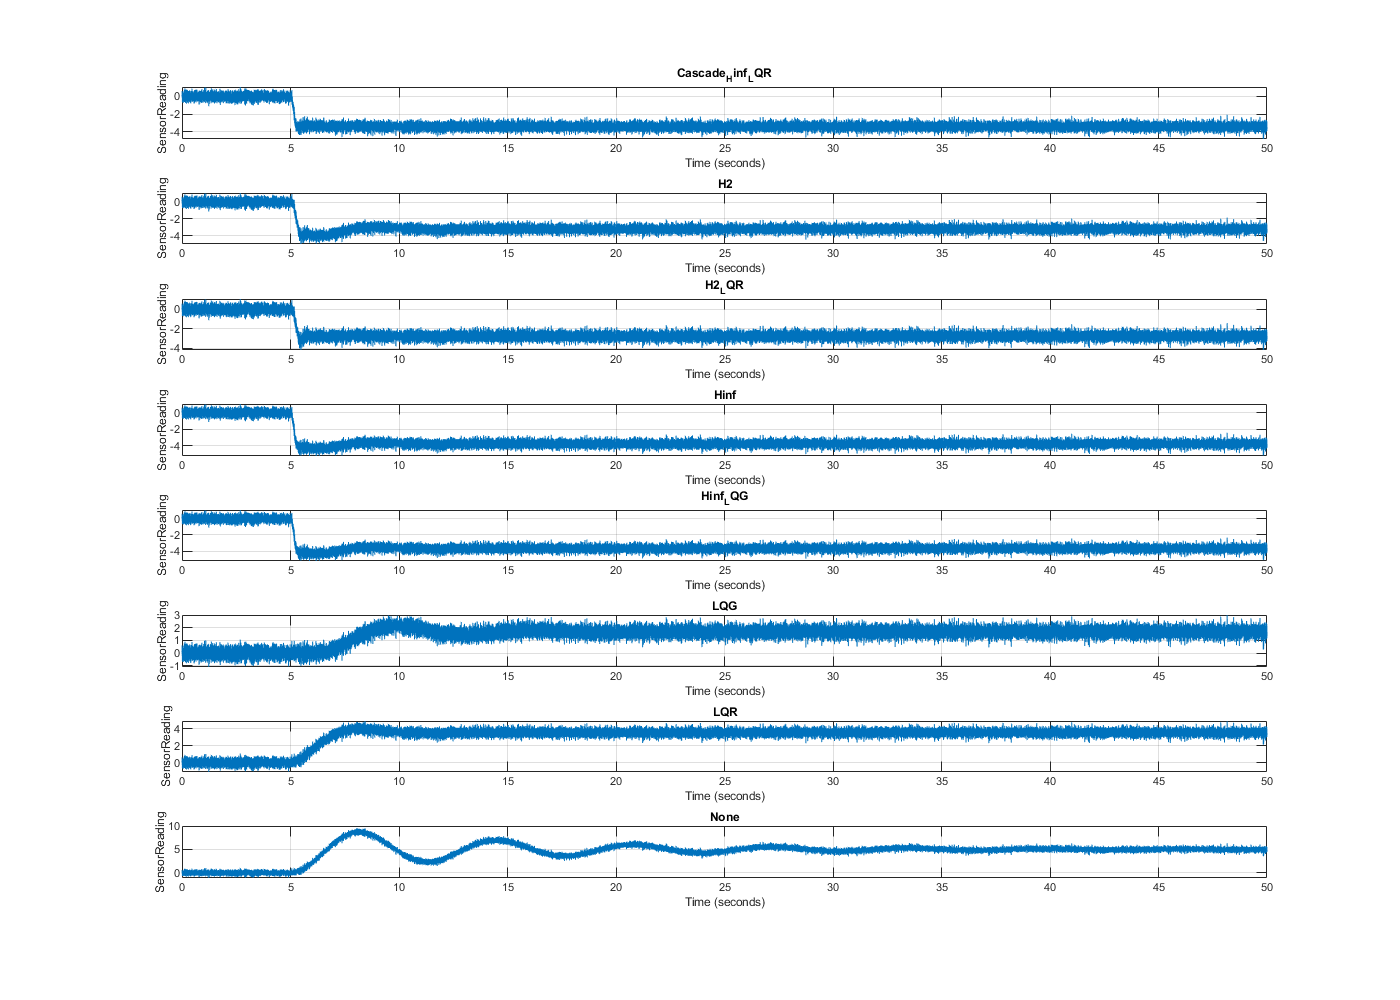

plot_map(results.Use_Noise);

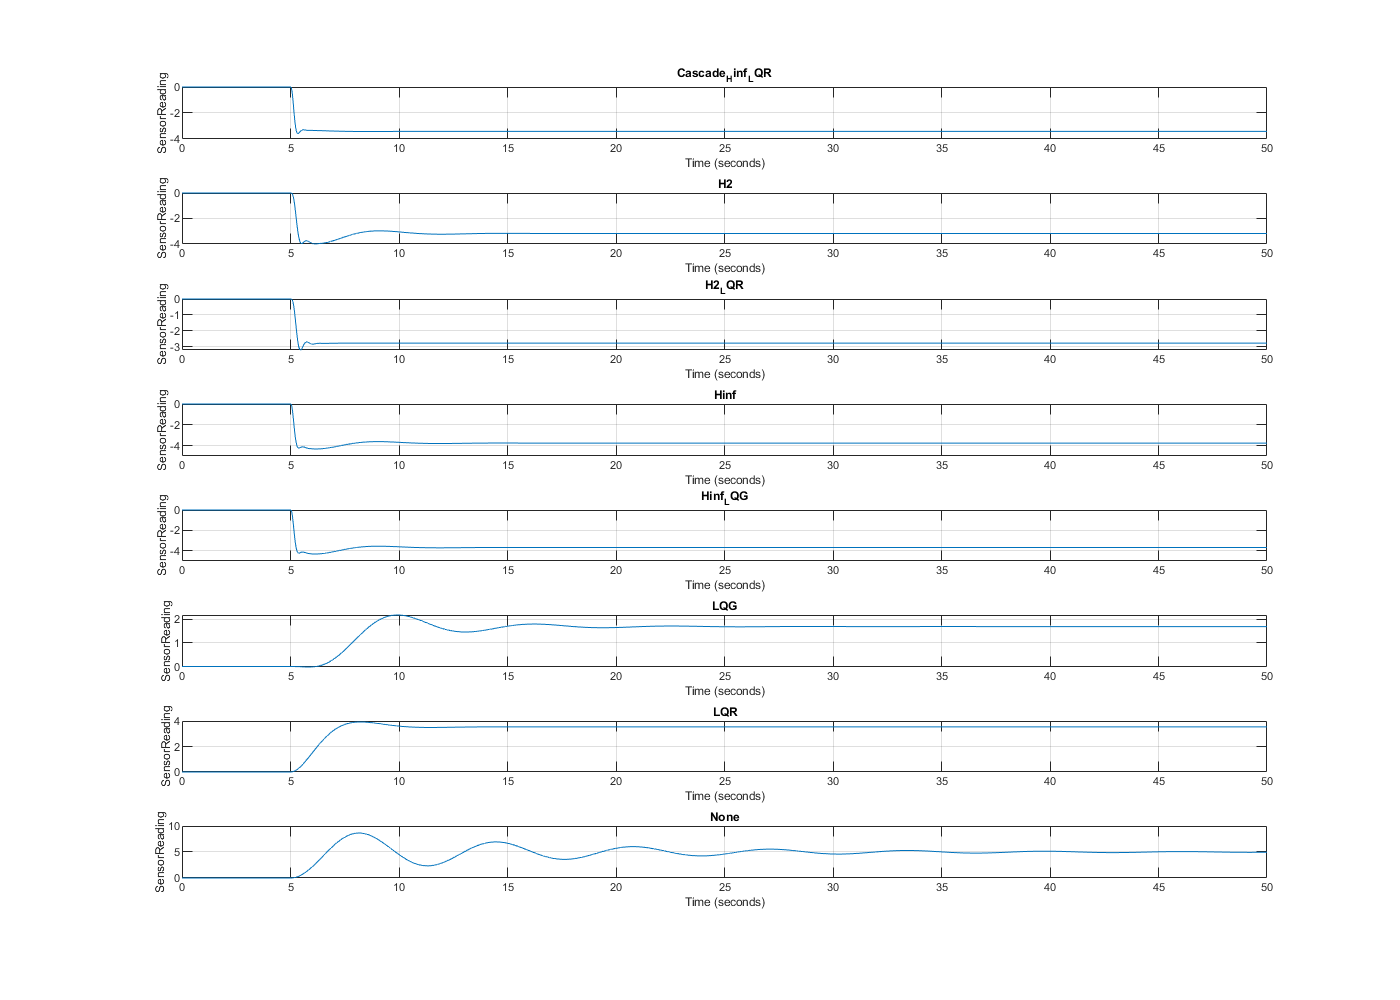

figure
plot_map(results.Dont_Use_Noise);

### Save controller and results data for report

save('data\Controllers','controller_*');
save('data\plants','plant*');
save('data\sim_results','results')